# Make Structure 3D Mapping Tool

## Load Data

% load average template
[ANO100, metaANO100] = nrrdread_cp('annotation_100.nrrd');

zsh:1: command not found: del
zsh:1: command not found: del


[DV100Size,AP100Size,LR100Size] = size(ANO100);

% load .mat data
load('structureInfoTableOh2014Sorted.mat')
load('MBStructureTreeData_raw.mat')

## See Images

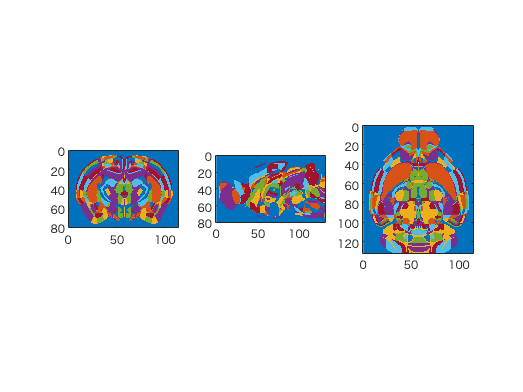

% Display one coronal section
figure;
tiledlayout(1,3);


ax1 = nexttile ;imagesc(squeeze(ANO100(:,66,:)));
clim(ax1,[1,2000]); colormap(ax1,lines(256)); axis equal;xlim(ax1,[0 LR100Size]); ylim(ax1,[0 DV100Size]);
ax2 = nexttile ;imagesc(squeeze(ANO100(:,:,57)));
clim(ax2,[1,2000]); colormap(ax2,lines(256)); axis equal; xlim(ax2,[0 AP100Size]); ylim(ax2,[0 DV100Size]);
ax3 = nexttile ;imagesc(squeeze(ANO100(40,:,:)));
clim(ax3,[1,2000]); colormap(ax3,lines(256)); axis equal; xlim(ax3,[0 LR100Size]); ylim(ax3,[0 AP100Size]);

## Make Annotation ID List

% of 3D annotation map
anoNumList = unique(ANO100); 
% of structure list of Oh
idListOh = table2array(structureInfoTableOh2014Sorted(:,11));

## Check Whether on the List

Lia_idOh = ismember(idListOh,anoNumList);
sum(Lia_idOh)

ans = 153

% make temporary list
NStructureOh = 213;
tempIDsListOh = idListOh .* Lia_idOh;
tempIDsListOhTxt = string(tempIDsListOh);

## Make Structure ID or Path List (String)

structureIdListOhTxt = strings(NStructureOh,1);
notfoundStructureIndexList_Init = double.empty();
ctr = 1;
for ns = 1:NStructureOh
    tempId = tempIDsListOh(ns);
    if tempId ~= 0
        structureIdListOhTxt(ns) = string(tempId);
    else
        notfoundStructureIndexList_Init(ctr,1) = ns;
        ctr = ctr+1;
        structureIdPath = string(table2array(structureInfoTableOh2014Sorted(ns,"structure_id_path")));
        structureIdListOhTxt(ns) = extractChildrenIdListTxtFromPath(structureIdPath);
    end
end

% make store list
store_structureIdTxtList = strings(NStructureOh,1);
for n = 1:NStructureOh
    tag = Lia_idOh(n);
    if tag == 1
        store_structureIdTxtList(n) = structureIdListOhTxt(n);
    end
end

## Check Downstream 1

% make ID List (Txt)
downstreamIDsListTxt_1 = string(size(notfoundStructureIndexList_Init)).';
for i = 1:length(notfoundStructureIndexList_Init)
    strind = notfoundStructureIndexList_Init(i);
    strpath = string(table2array(structureInfoTableOh2014Sorted(strind,"structure_id_path")));
    childrenIdListTxt = extractChildrenIdListTxtFromPath(strpath);
    downstreamIDsListTxt_1(i) = childrenIdListTxt;
end

% check whether in the ID List
downstreamLiaListTxt_1 = string(size(notfoundStructureIndexList_Init)).';
downstreamLiaRatioList_1 = zeros(size(notfoundStructureIndexList_Init));
for i = 1:length(notfoundStructureIndexList_Init)
    IDList = jsondecode(downstreamIDsListTxt_1(i));
    LiaList = zeros(length(IDList),1);
    for j = 1:length(IDList)
        ID = IDList(j);
        LiaList(j) = ismember(ID,anoNumList);
    end
    downstreamLiaListTxt_1(i) = jsonencode(LiaList);
    downstreamLiaRatioList_1(i) = sum(LiaList) / length(LiaList);
end

% make incomplete index list & store list
incompleteIndexList_1 = double.empty();
ctr = 1;
for i = 1:length(notfoundStructureIndexList_Init)
    ratio = downstreamLiaRatioList_1(i);
    if ratio ~= 1 % incomplete index list
        incompleteIndexList_1(ctr,1) = i;
        ctr = ctr + 1;
    elseif ratio == 1 % store list
        index = notfoundStructureIndexList_Init(i);
        store_structureIdTxtList(index) = downstreamIDsListTxt_1(i);
    end
end

## Check Downstream 2

% check incomplete list
downstreamIDsListTxt_2 = strings(size(incompleteIndexList_1));
for i = 1:length(incompleteIndexList_1)
    index = incompleteIndexList_1(i);
    LiaList = jsondecode(downstreamLiaListTxt_1(index));
    IDsList = jsondecode(downstreamIDsListTxt_1(index));
    IDsTxtStorei = strings([length(LiaList),1]);
    for j = 1:length(LiaList) 
        ID = IDsList(j);
        if LiaList(j) == 0            
            structureIdPath = string(table2array(structureInfoTableOh2014Sorted(notfoundStructureIndexList_Init(incompleteIndexList_1(i)),'structure_id_path')));
            childrenIdListTxt = extractChildrenIdListTxtFromIDAndPath(ID,structureIdPath);
        elseif LiaList(j) == 1
            childrenIdListTxt = num2str(ID);
        end
        IDsTxtStorei(j,1) = childrenIdListTxt;
    end
    downstreamIDsListTxt_2(i) = jsonencode(IDsTxtStorei);
end

% check terminal manually
%{
for i = 1:length(incompleteIndexList_1)
    index = incompleteIndexList_1(i)
    LiaList = jsondecode(downstreamLiaListTxt_1(index))
    IDsTxtList = jsondecode(downstreamIDsListTxt_2(i))
end
%}

% delete terminal
txtErrorcode3 = "error3:inputID is terminal";
downstreamIDsListTxt_2_terminalDelete = strings(size(downstreamIDsListTxt_2));
downstreamLiaListTxt_1_terminalDelete = strings(size(downstreamLiaListTxt_1));
for i = 1:length(incompleteIndexList_1)
    index = incompleteIndexList_1(i);
    LiaList = jsondecode(downstreamLiaListTxt_1(index));
    IDsTxtList = jsondecode(downstreamIDsListTxt_2(i));
    deleteIndexList = double.empty();
    ctr = 1;
    for j = 1:length(LiaList)
        if LiaList(j) == 0
            childrenTxt = IDsTxtList(j);
            if childrenTxt == txtErrorcode3
                [index,j];
                deleteIndexList(ctr) = j;
                ctr = ctr + 1;
            end
        end        
    end

    if ctr > 1
        LiaList(deleteIndexList) = [];
        IDsTxtList(deleteIndexList) = [];
    end
    downstreamIDsListTxt_2_terminalDelete(i) = jsonencode(IDsTxtList);
    downstreamLiaListTxt_1_terminalDelete(index) = jsonencode(LiaList);
end

% store list of terminal
for i = 1:length(incompleteIndexList_1)
    index1 = incompleteIndexList_1(i);
    LiaList = jsondecode(downstreamLiaListTxt_1_terminalDelete(index1));
    LiaRatio = sum(LiaList) / length(LiaList);
    if LiaRatio == 1
        index = notfoundStructureIndexList_Init(index1);
        store_structureIdTxtList(index) = downstreamIDsListTxt_2_terminalDelete(i);
    end
end

% check in the annotation ID List & terminal

%downstreamLiaListTxt2 = strings(size(downstreamIDsListTxt_2_terminalDelete));
%terminalCheckList = zeros(length(incompleteIndexList_1));
for i = 1:length(incompleteIndexList_1)
    index = incompleteIndexList_1(i);
    LiaList = jsondecode(downstreamLiaListTxt_1_terminalDelete(index));
    IDsTxtList = jsondecode(downstreamIDsListTxt_2_terminalDelete(i));
    if isempty(LiaList) == 0
        for j = 1:length(LiaList)
            if LiaList(j) == 0
                index
                j
                IDsTxtList(j)
                childrenIdList = jsondecode(cell2mat(IDsTxtList(j)));
                Lia = ismember(childrenIdList,anoNumList)
                % check terminal
                terminalChecker = ones(length(childrenIdList),1);
                structureIdPath = string(table2array(structureInfoTableOh2014Sorted(notfoundStructureIndexList_Init(incompleteIndexList_1(i)),'structure_id_path')));
                for k = 1:length(Lia)
                    ID = childrenIdList(k);
                    childrenIdListTxt = extractChildrenIdListTxtFromIDAndPath(ID,structureIdPath);
                    if childrenIdListTxt == txtErrorcode3
                        terminalChecker(k) = 0;
                    end
                end
                terminalCheckerSum = sum(terminalChecker)
            end
        end  
    end
end

index = 6

j = 7

ans = 1×1 の cell 配列
    {'[4.80149234E+8,4.80149238E+8,4.80149242E+8,4.80149246E+8,4.8014925E+8,4.80149254E+8]'}


Lia = 6×1 の logical 配列
   0
   0
   0
   0
   0
   0


terminalCheckerSum = 0

index = 20

j = 1

ans = 1×1 の cell 配列
    {'[3.1278255E+8,3.12782554E+8,3.12782558E+8,3.12782562E+8,3.12782566E+8,3.1278257E+8]'}


Lia = 6×1 の logical 配列
   1
   1
   1
   1
   1
   1


terminalCheckerSum = 0

index = 20

j = 2

ans = 1×1 の cell 配列
    {'[3.12782604E+8,3.12782608E+8,3.12782612E+8,3.12782616E+8,3.1278262E+8,3.12782624E+8]'}


Lia = 6×1 の logical 配列
   1
   1
   1
   1
   1
   1


terminalCheckerSum = 0

index = 21

j = 6

ans = 1×1 の cell 配列
    {'[4.80149262E+8,4.80149266E+8,4.8014927E+8,4.80149274E+8,4.80149278E+8,4.80149282E+8]'}


Lia = 6×1 の logical 配列
   0
   0
   0
   0
   0
   0


terminalCheckerSum = 0

index = 21

j = 7

ans = 1×1 の cell 配列
    {'[4.8014929E+8,4.80149294E+8,4.80149298E+8,4.80149302E+8,4.80149306E+8,4.8014931E+8]'}


Lia = 6×1 の logical 配列
   0
   0
   0
   0
   0
   0


terminalCheckerSum = 0

index = 21

j = 8

ans = 1×1 の cell 配列
    {'[4.80149318E+8,4.80149322E+8,4.80149326E+8,4.8014933E+8,4.80149334E+8,4.80149338E+8]'}


Lia = 6×1 の logical 配列
   0
   0
   0
   0
   0
   0


terminalCheckerSum = 0

index = 24

j = 7

ans = 1×1 の cell 配列
    {'[4.80149206E+8,4.8014921E+8,4.80149214E+8,4.80149218E+8,4.80149222E+8,4.80149226E+8]'}


Lia = 6×1 の logical 配列
   0
   0
   0
   0
   0
   0


terminalCheckerSum = 0

index = 43

j = 4

ans = 1×1 の cell 配列
    {'[742,751,758]'}


Lia = 3×1 の logical 配列
   0
   0
   0


terminalCheckerSum = 0

index = 43

j = 5

ans = 1×1 の cell 配列
    {'[775,782,790]'}


Lia = 3×1 の logical 配列
   0
   0
   0


terminalCheckerSum = 0

index = 43

j = 6

ans = 1×1 の cell 配列
    {'[807,815,823]'}


Lia = 3×1 の logical 配列
   0
   0
   0


terminalCheckerSum = 0

index = 60

j = 1

ans = 1×1 の cell 配列
    {'[10716,10715,10714]'}


Lia = 3×1 の logical 配列
   0
   0
   0


terminalCheckerSum = 0

index = 60

j = 2

ans = 1×1 の cell 配列
    {'[10719,10718,10717]'}


Lia = 3×1 の logical 配列
   0
   0
   0


terminalCheckerSum = 0

% memo : all terminal

% store List
for i = 1:length(incompleteIndexList_1)
    index = incompleteIndexList_1(i);
    LiaList = jsondecode(downstreamLiaListTxt_1_terminalDelete(index));
    IDsTxtList = jsondecode(downstreamIDsListTxt_2_terminalDelete(i));
    if isempty(LiaList) == 0
        index
        deleteIndexList = double.empty();
        ctr = 1;
        for j = 1:length(LiaList)
            if LiaList(j) == 0
                childrenIdList = jsondecode(cell2mat(IDsTxtList(j)));
                Lia = ismember(childrenIdList,anoNumList);
                if sum(Lia) == 0
                    deleteIndexList(ctr) = j;
                    ctr = ctr + 1;
                end
            end
        end
        if index ~= 20
            IDsTxtList(deleteIndexList) = [];
            IDsList = cellfun(@str2num,IDsTxtList);
            hoge = jsonencode(IDsList);
            index0 = notfoundStructureIndexList_Init(index);
            store_structureIdTxtList(index0) = jsonencode(IDsList);
        end
    end
end

index = 6

index = 12

index = 16

index = 19

index = 20

index = 21

index = 22

index = 23

index = 24

index = 41

index = 43

index = 44

index = 45

index = 60

% manually add index 20
% index = 20
i = 5;
idListtxt_20 = jsondecode(downstreamIDsListTxt_2_terminalDelete(i));
idList_20_1 = jsondecode(string(idListtxt_20(1)));
idList_20_2 = jsondecode(string(idListtxt_20(2)));
idList_20 = [idList_20_1;idList_20_2];
index = notfoundStructureIndexList_Init(20);
store_structureIdTxtList(index) = jsonencode(idList_20);

## Check Upstream

% index = 59
indexList = [59 60];
for index = indexList
    structureIdPath = string(table2array(structureInfoTableOh2014Sorted(index,'structure_id_path')));
    upstreamID = extractUpstreamID(structureIdPath)
    ismember(upstreamID,anoNumList)
end

upstreamID = 502

ans = logical
   1


upstreamID = 502

ans = logical
   1


indexList = [59 60];
for index = indexList
    structureIdPath = string(table2array(structureInfoTableOh2014Sorted(index,'structure_id_path')));
    upstreamID = extractUpstreamID(structureIdPath);
    store_structureIdTxtList(index) = jsonencode(upstreamID);
end

% see ID502
hoge = (ANO100 == 502);
hoge_linInd = find(hoge);
[hoge_y,hoge_x,hoge_z] = ind2sub([DV100Size,AP100Size,LR100Size],hoge_linInd);

## Make Structure ID & Connection Matrix Index List

% make structureID List
conMatOhIndAndStrIDList = double.empty([0,2]);
ctr = 1;
for n = 1:NStructureOh
    structureIdListn = jsondecode(store_structureIdTxtList(n));
    nList = length(structureIdListn);
    conMatOhIndAndStrIDList(ctr:ctr+nList-1,1) = n;
    conMatOhIndAndStrIDList(ctr:ctr+nList-1,2) = structureIdListn;
    ctr = ctr + nList;
end

## Make Annotation Voxcels of Connection Matrix Index

ANO100_ConMatIndOh = ANO100;

for y = 1:DV100Size  
    for x = 1:AP100Size
        for z = 1:LR100Size
            strID = ANO100(y,x,z);
            if strID ~= 0
                Lia = ismember(strID,conMatOhIndAndStrIDList(:,2));
                if Lia == 1
                    k = find(conMatOhIndAndStrIDList(:,2) == strID,1);
                    conMatInd = conMatOhIndAndStrIDList(k,1);
                    ANO100_ConMatIndOh(y,x,z) = conMatInd;
                else
                    ANO100_ConMatIndOh(y,x,z) = -1;
                end
            end
        end
    end
end

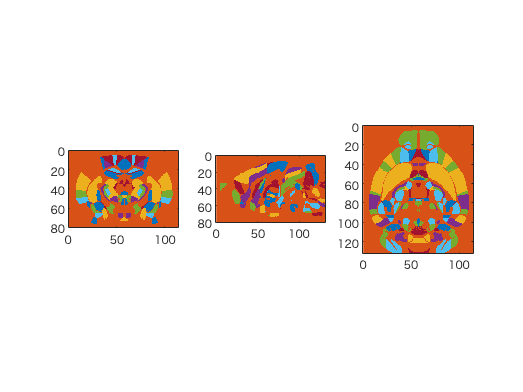

% See
figure;
tiledlayout(1,3);

ax1 = nexttile ;imagesc(squeeze(ANO100_ConMatIndOh(:,66,:)));
clim(ax1,[-1,213]); colormap(ax1,lines(256)); axis equal;xlim(ax1,[0 LR100Size]); ylim(ax1,[0 DV100Size]);
ax2 = nexttile ;imagesc(squeeze(ANO100_ConMatIndOh(:,:,57)));
clim(ax2,[-1,213]); colormap(ax2,lines(256)); axis equal; xlim(ax2,[0 AP100Size]); ylim(ax2,[0 DV100Size]);
ax3 = nexttile ;imagesc(squeeze(ANO100_ConMatIndOh(40,:,:)));
clim(ax3,[-1,213]); colormap(ax3,lines(256)); axis equal; xlim(ax3,[0 LR100Size]); ylim(ax3,[0 AP100Size]);

## Extract Coordinates of Each Structure (Right Hemisphere)

% memo: right hemisphere (58 <= z <=114) 
ANO100_ConMatIndOh_onlyRight = ANO100_ConMatIndOh;
ANO100_ConMatIndOh_onlyRight(:,:,1:57) = 0;

% make coordinate list
structureOhCoordTxtList_onlyRight = strings(NStructureOh,1); 
for ns = 1:NStructureOh
    linInd = find(ANO100_ConMatIndOh_onlyRight == ns);
    [IY,IX,IZ] = ind2sub([DV100Size,AP100Size,LR100Size],linInd);
    structureOhCoordTxtList_onlyRight(ns,1) = jsonencode([IY IX IZ]);
end

## Calculate Center of Structure (except 59,60)

centerCoordList = zeros(NStructureOh,3);
for ns = 1:NStructureOh
    coordList = jsondecode(structureOhCoordTxtList_onlyRight(ns));
    if isempty(coordList) ~= 1
        centerCoord = mean(coordList,1);
        centerCoordList(ns,:) = centerCoord;        
    end
end

## Check Center & Structure Region

%{
for ns = 46:50%:
    coordList = jsondecode(structureOhCoordTxtList_onlyRight(ns));
    centerCoord = centerCoordList(ns,:);
    figure;
    Y = coordList(:,1);
    X = coordList(:,2);
    Z = coordList(:,3);
    S = 10;
    C = 'b';
    scatter3(Y,X,Z,S,C,'.')
    hold on
    YC = centerCoord(1);
    XC = centerCoord(2);
    ZC = centerCoord(3);
    scatter3(YC,XC,ZC,50,'r','o','filled')
    axis equal
    xlim([0,DV100Size])
    ylim([0,AP100Size])
    zlim([0,LR100Size])
    hiatus = 1;
    xticks([0+hiatus,DV100Size-hiatus])
    xticklabels({'Superior','Inferior'})
    yticks([0+hiatus,AP100Size-hiatus])
    yticklabels({'Anterior','Posterior'})
    zticks([0+hiatus,LR100Size-hiatus])
    zticklabels({'Left','Right'})
    hold on 
    medialPlaneColorImage = squeeze(ANO100_ConMatIndOh(:,:,57)).';%
    heightZ = ones([AP100Size,DV100Size]) .* 57;
    surf(heightZ,medialPlaneColorImage,'EdgeColor','none','FaceColor','texturemap','FaceAlpha',0.5)
    clim([-1,256]); colormap(lines(256))
    acronymName = string(table2cell(structureInfoTableOh2014Sorted(ns,'acronym')));
    structureName = string(table2cell(structureInfoTableOh2014Sorted(ns,'name')));
    title(strcat('No.',num2str(ns),':  ',structureName,' (',acronymName,')'))
    pause
    close
end
%}
    

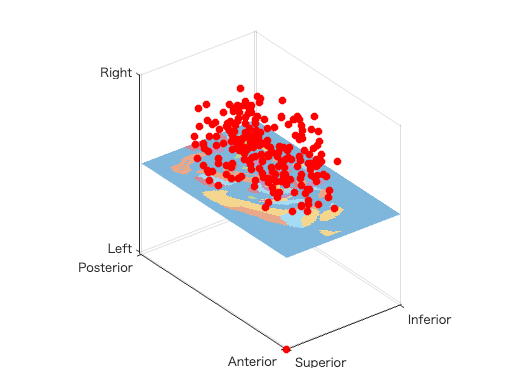

% See Only Center
figure;
YCs = centerCoordList(:,1);
XCs = centerCoordList(:,2);
ZCs = centerCoordList(:,3);
scatter3(YCs,XCs,ZCs,50,'r','o','filled')
axis equal
xlim([0,DV100Size])
ylim([0,AP100Size])
zlim([0,LR100Size])
hiatus = 1;
xticks([0+hiatus,DV100Size-hiatus])
xticklabels({'Superior','Inferior'})
yticks([0+hiatus,AP100Size-hiatus])
yticklabels({'Anterior','Posterior'})
zticks([0+hiatus,LR100Size-hiatus])
zticklabels({'Left','Right'})
hold on 
medialPlaneColorImage = squeeze(ANO100_ConMatIndOh(:,:,57)).';%
heightZ = ones([AP100Size,DV100Size]) .* 57;
surf(heightZ,medialPlaneColorImage,'EdgeColor','none','FaceColor','texturemap','FaceAlpha',0.5)
clim([-1,256]); colormap(lines(256))

## (Tentative) Devide SUB Structure Manually (59,60)

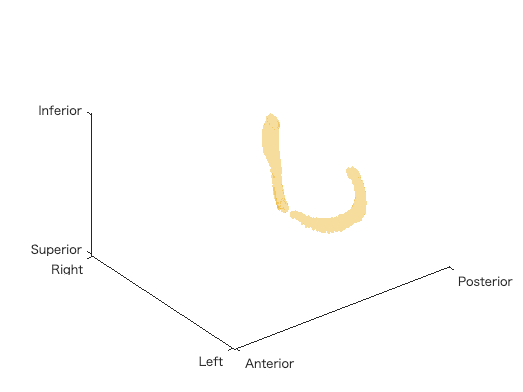

colorList = lines;
figure
for ns = 59
%erodeim = imerode(ANO100_ConMatIndOh_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = (ANO100_ConMatIndOh == ns);
erodeim = permute(erodeim,[3 2 1]);
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end

view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})

ANO100_ConMatIndOh_SUBd = (ANO100_ConMatIndOh == 59);
ANO100_ConMatIndOh_SUBd(30:DV100Size,:,:) = 0;
ANO100_ConMatIndOh_SUBd(:,90:AP100Size,:) = 0;
ANO100_ConMatIndOh_SUBv = (ANO100_ConMatIndOh == 59) - ANO100_ConMatIndOh_SUBd;
ANO100_ConMatIndOh_subCompManually = ANO100_ConMatIndOh + uint32(ANO100_ConMatIndOh_SUBv);
ANO100_ConMatIndOh_subCompManually_onlyRight = ANO100_ConMatIndOh_subCompManually;
ANO100_ConMatIndOh_subCompManually_onlyRight(:,:,1:57) = 0;

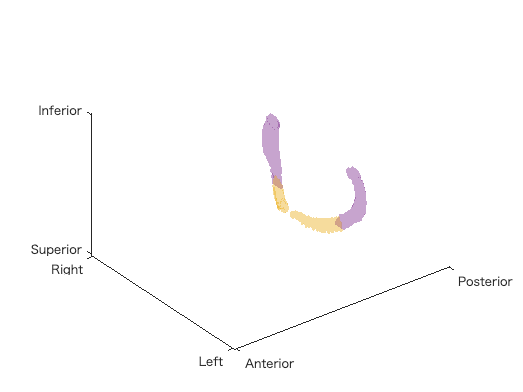

figure
for ns = 59:60
%erodeim = imerode(ANO100_ConMatIndOh_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = (ANO100_ConMatIndOh_subCompManually == ns);
erodeim = permute(erodeim,[3 2 1]);
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})

## Calculate Center by Gaussian Filter

gaussianCenterCoordList = zeros(NStructureOh,3);
gaussianCenterInfoList = zeros(NStructureOh,2);
for ns = 1:NStructureOh
    structureAnnotationNs = (ANO100_ConMatIndOh_onlyRight == ns);
    nPoint = sum(structureAnnotationNs,'all');
    sigmaunit = 0.3;
    sigma = sigmaunit * nthroot(nPoint,3);
    if sigma == 0
        sigma = sigmaunit;
    end
    convStrAnoNs = imgaussfilt3(double(structureAnnotationNs),sigma,'Padding',0,'FilterDomain','spatial');
    [M,I] =  max(convStrAnoNs,[],'all');
    [xcmc,yxmc,zcmc] = ind2sub([DV100Size,AP100Size,LR100Size],I);
    gaussianCenterCoordList(ns,:) = [xcmc,yxmc,zcmc];
    gaussianCenterInfoList(ns,1) = M;
    gaussianCenterInfoList(ns,2) = sigma;
end
maxk(gaussianCenterInfoList(:,1),5)

ans =     0.7808
    0.7739
    0.7722
    0.7706
    0.7700


diffCenterGaussList = centerCoordList - gaussianCenterCoordList;
[M,I] =  max(vecnorm(diffCenterGaussList.'))

M = 20.6606

I = 64

% sub comp version
gaussianCenterCoordList_subCompManually = zeros(NStructureOh,3);
gaussianCenterInfoList_subCompManually = zeros(NStructureOh,2);
for ns = 1:NStructureOh
    structureAnnotationNs = (ANO100_ConMatIndOh_subCompManually_onlyRight == ns);
    nPoint = sum(structureAnnotationNs,'all');
    sigmaunit = 0.3;
    sigma = sigmaunit * nthroot(nPoint,3);
    if sigma == 0
        sigma = sigmaunit;
    end
    convStrAnoNs = imgaussfilt3(double(structureAnnotationNs),sigma,'Padding',0,'FilterDomain','spatial');
    [M,I] =  max(convStrAnoNs,[],'all');
    [xcmc,yxmc,zcmc] = ind2sub([DV100Size,AP100Size,LR100Size],I);
    gaussianCenterCoordList_subCompManually(ns,:) = [xcmc,yxmc,zcmc];
    gaussianCenterInfoList_subCompManually(ns,1) = M;
    gaussianCenterInfoList_subCompManually(ns,2) = sigma;
end
maxk(gaussianCenterInfoList_subCompManually(:,1),5)

ans =     0.7808
    0.7739
    0.7722
    0.7706
    0.7700


## See Convolution Center

%{
for ns = 1:5%:
    coordList = jsondecode(structureOhCoordTxtList_onlyRight(ns));
    centerCoord = gaussianCenterCoordList(ns,:);
    figure;
    Y = coordList(:,1);
    X = coordList(:,2);
    Z = coordList(:,3);
    S = 10;
    C = 'b';
    scatter3(Y,X,Z,S,C,'.')
    hold on
    YC = centerCoord(1);
    XC = centerCoord(2);
    ZC = centerCoord(3);
    scatter3(YC,XC,ZC,50,'r','o','filled')
    axis equal
    xlim([0,DV100Size])
    ylim([0,AP100Size])
    zlim([0,LR100Size])
    hiatus = 1;
    xticks([0+hiatus,DV100Size-hiatus])
    xticklabels({'Superior','Inferior'})
    yticks([0+hiatus,AP100Size-hiatus])
    yticklabels({'Anterior','Posterior'})
    zticks([0+hiatus,LR100Size-hiatus])
    zticklabels({'Left','Right'})
    hold on 
    medialPlaneColorImage = squeeze(ANO100_ConMatIndOh(:,:,57)).';%
    heightZ = ones([AP100Size,DV100Size]) .* 57;
    surf(heightZ,medialPlaneColorImage,'EdgeColor','none','FaceColor','texturemap','FaceAlpha',0.5)
    clim([-1,256]); colormap(lines(256))
    acronymName = string(table2cell(structureInfoTableOh2014Sorted(ns,'acronym')));
    structureName = string(table2cell(structureInfoTableOh2014Sorted(ns,'name')));
    title(strcat('No.',num2str(ns),':  ',structureName,' (',acronymName,')'))
    pause
    close
end
%}

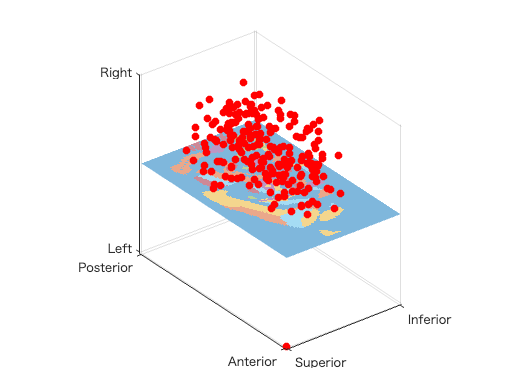

% See Only Center
figure;
YCs = gaussianCenterCoordList(:,1);
XCs = gaussianCenterCoordList(:,2);
ZCs = gaussianCenterCoordList(:,3);
scatter3(YCs,XCs,ZCs,50,'r','o','filled')
axis equal
xlim([0,DV100Size])
ylim([0,AP100Size])
zlim([0,LR100Size])
hiatus = 1;
xticks([0+hiatus,DV100Size-hiatus])
xticklabels({'Superior','Inferior'})
yticks([0+hiatus,AP100Size-hiatus])
yticklabels({'Anterior','Posterior'})
zticks([0+hiatus,LR100Size-hiatus])
zticklabels({'Left','Right'})
hold on 
medialPlaneColorImage = squeeze(ANO100_ConMatIndOh(:,:,57)).';%
heightZ = ones([AP100Size,DV100Size]) .* 57;
surf(heightZ,medialPlaneColorImage,'EdgeColor','none','FaceColor','texturemap','FaceAlpha',0.5)
clim([-1,256]); colormap(lines(256))

## Make Major Region Annotation

% make major region index list
majorRegionIndexList = zeros(NStructureOh,1);
majorRegionIndexList(1:38) = 1; % "Isocortex"
majorRegionIndexList(39:49) = 2; % "Olfactory Areas"
majorRegionIndexList(50:60) = 3; % "Hippocampal Formation"
majorRegionIndexList(61:67) = 4; % "Cortical Subplate"
majorRegionIndexList(68:79) = 5; % "Striatum"
majorRegionIndexList(80:87) = 6; % "Pallidum"
majorRegionIndexList(88:122) = 7; % "Thalamus"
majorRegionIndexList(123:142) = 8; % "Hypothalamus"
majorRegionIndexList(143:163) = 9; % "Midbrain"
majorRegionIndexList(164:176) = 10; % "Pons"
majorRegionIndexList(177:201) = 11; % "Medulla"
majorRegionIndexList(202:210) = 12; % "Cerebellar Cortex"
majorRegionIndexList(211:213) = 13; % "Cerebellar Nuclei"

NMajorRegion = 13;
majorRegionNameList = strings(NMajorRegion,1);
majorRegionNameList(1) = "Isocortex";
majorRegionNameList(2) = "Olfactory Areas";
majorRegionNameList(3) = "Hippocampal Formation";
majorRegionNameList(4) = "Cortical Subplate";
majorRegionNameList(5) = "Striatum";
majorRegionNameList(6) = "Pallidum";
majorRegionNameList(7) = "Thalamus";
majorRegionNameList(8) = "Hypothalamus";
majorRegionNameList(9) = "Midbrain";
majorRegionNameList(10) = "Pons";
majorRegionNameList(11) = "Medulla";
majorRegionNameList(12) = "Cerebellar Cortex";
majorRegionNameList(13) = "Cerebellar Nuclei";

% make ANO100 Major region
ANO100_majorRegion = zeros(size(ANO100_ConMatIndOh_subCompManually));
for dv = 1:DV100Size
    for ap = 1:AP100Size
        for lr = 1:LR100Size
            index = ANO100_ConMatIndOh_subCompManually(dv,ap,lr);
            if index ~= 0;
                mrIndex = majorRegionIndexList(index);
                ANO100_majorRegion(dv,ap,lr) = mrIndex;
            end
        end
    end
end
ANO100_majorRegion_onlyRight = ANO100_majorRegion;
ANO100_majorRegion_onlyRight(:,:,1:57) = 0;

## Check Major Region

colorList13 = zeros(13,3);
colorList13(1,:) = [1 0 0];
colorList13(2,:) = [0 1 0];
colorList13(3,:) = [0 0 1];
colorList13(4,:) = [0 1 1];
colorList13(5,:) = [1 0 1];
colorList13(6,:) = [1 1 0];
colorList13(7,:) = [0 0.4470 0.7410];
colorList13(8,:) = [0.8500 0.3250 0.0980];
colorList13(9,:) = [0.9290 0.6940 0.1250];
colorList13(10,:) = [0.4940 0.1840 0.5560];
colorList13(11,:) = [0.4660 0.6740 0.1880];
colorList13(12,:) = [0.3010 0.7450 0.9330];
colorList13(13,:) = [0.6350 0.0780 0.1840];

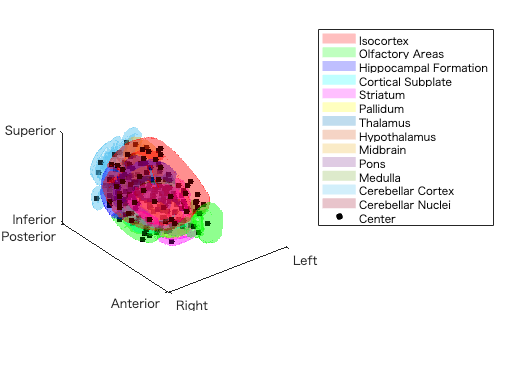

erodeSize = 2;
legendLabel = strings(NMajorRegion+1,1);
legendLabel(1:NMajorRegion) = majorRegionNameList;
legendLabel(14) = "Center";

figure
for nmr = 1:NMajorRegion
erodeim = imerode(ANO100_majorRegion_onlyRight == nmr,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[2 3 1]);
erodeim = flip(erodeim,2);
erodeim = flip(erodeim,3);
strctSurfNs = isosurface(1:LR100Size,1:AP100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList13(nmr,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
CDVs = gaussianCenterCoordList_subCompManually(:,1);
CDVs = -(CDVs - DV100Size/2 - 0.5) + DV100Size/2 + 0.5;
CAPs = gaussianCenterCoordList_subCompManually(:,2);
CLRs = gaussianCenterCoordList_subCompManually(:,3);
CLRs = -(CLRs - LR100Size/2 - 0.5) + LR100Size/2 + 0.5;
sz = 30;
scatter3(CLRs,CAPs,CDVs,sz,'k','o','filled')
view(3)
axis equal
xlim([0,LR100Size])
ylim([0,AP100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,LR100Size-hiatus])
xticklabels({'Right','Left'})
yticks([0+hiatus,AP100Size-hiatus])
yticklabels({'Anterior','Posterior'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Inferior','Superior'})

legend(legendLabel)

## Save Data (Tentative)

save('tentative_ANO100_ConMatIndOh.mat','ANO100_ConMatIndOh')
save('tentative_ANO100_ConMatIndOh_onlyRight.mat','ANO100_ConMatIndOh_onlyRight')
save('tentative_gaussianCenterCoordList.mat','gaussianCenterCoordList')


save('tentative_ANO100_ConMatIndOh_subCompManually.mat','ANO100_ConMatIndOh_subCompManually')
save('tentative_ANO100_ConMatIndOh_subCompManually_onlyRight.mat','ANO100_ConMatIndOh_subCompManually_onlyRight')
save('tentative_gaussianCenterCoordList_subCompManually.mat','gaussianCenterCoordList_subCompManually')

save('ANO100_majorRegion.mat','ANO100_majorRegion')
save('ANO100_majorRegion_onlyRight.mat','ANO100_majorRegion_onlyRight')
save('majorRegionIndexList.mat','majorRegionIndexList')
save('majorRegionNameList.mat','majorRegionNameList')
save('colorList13.mat','colorList13')

## See Structure Surface

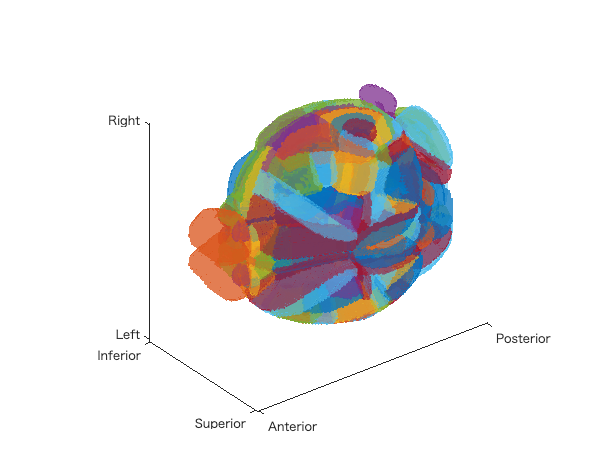

% non erode 
colorList = lines(NStructureOh);
figure
for ns = 1:NStructureOh
strctSurfNs = isosurface(1:AP100Size,1:DV100Size,1:LR100Size,ANO100_ConMatIndOh == ns,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.5,'EdgeColor','none');
hold on
end
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,DV100Size])
zlim([0,LR100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,DV100Size-hiatus])
yticklabels({'Superior','Inferior'})
zticks([0+hiatus,LR100Size-hiatus])
zticklabels({'Left','Right'})

% erode on
%{
colorList = lines(NStructureOh);
erodeSize = 2;
figure
for ns = 1:NStructureOh
strctSurfNs = isosurface(1:AP100Size,1:DV100Size,1:LR100Size,imerode(ANO100_ConMatIndOh == ns,ones(erodeSize,erodeSize,erodeSize)),0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.5,'EdgeColor','none');
hold on
end
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,DV100Size])
zlim([0,LR100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,DV100Size-hiatus])
yticklabels({'Superior','Inferior'})
zticks([0+hiatus,LR100Size-hiatus])
zticklabels({'Left','Right'})
%}

% erode on, right only, center point
%{
colorList = lines(NStructureOh);
erodeSize = 2;
figure
for ns = 1:NStructureOh
strctSurfNs = isosurface(1:AP100Size,1:DV100Size,1:LR100Size,imerode(ANO100_ConMatIndOh_subCompManually_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize)),0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList_subCompManually(:,1);
XCs = gaussianCenterCoordList_subCompManually(:,2);
ZCs = gaussianCenterCoordList_subCompManually(:,3);
scatter3(XCs,YCs,ZCs,50,'r','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,DV100Size])
zlim([0,LR100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,DV100Size-hiatus])
yticklabels({'Superior','Inferior'})
zticks([0+hiatus,LR100Size-hiatus])
zticklabels({'Left','Right'})
%}

% erode on, right only, center point, change axis order
%{
colorList = lines(NStructureOh);
erodeSize = 2;
figure
for ns = 1:NStructureOh
erodeim = imerode(ANO100_ConMatIndOh_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[3 2 1]);
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList(:,1);
XCs = gaussianCenterCoordList(:,2);
ZCs = gaussianCenterCoordList(:,3);
scatter3(XCs,ZCs,YCs,50,'r','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})
%}

% same color
%{
colorList = lines(NStructureOh);
erodeSize = 2;
figure
for ns = 1:NStructureOh
erodeim = imerode(ANO100_ConMatIndOh_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[3 2 1]);
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(1,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList(:,1);
XCs = gaussianCenterCoordList(:,2);
ZCs = gaussianCenterCoordList(:,3);
scatter3(XCs,ZCs,YCs,50,'r','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})
%}

% try other colormap
%{
colorList = jet(NStructureOh);
erodeSize = 2;
figure
for ns = 1:NStructureOh
erodeim = imerode(ANO100_ConMatIndOh_subCompManually_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[3 2 1]);
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList_subCompManually(:,1);
XCs = gaussianCenterCoordList_subCompManually(:,2);
ZCs = gaussianCenterCoordList_subCompManually(:,3);
scatter3(XCs,ZCs,YCs,50,'r','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})
%}

## Try to See U,V Value (after 'checkFlowforCCAAnallysis_Oh~~')

ccaCompDim = 3;
[uValuesPerRegion,vValuesPerRegion] = calculateUVperRegion(CCAResults_NMF50_sorted,NMFResults_Oh2014Sorted_50.W,geneExp_source,geneExp_target);

% calculate colormap index
absMaxListU = max(uValuesPerRegion,[],1,'ComparisonMethod','abs');
absMaxListV = max(vValuesPerRegion,[],1,'ComparisonMethod','abs');
uValuePerRegionDim1 = uValuesPerRegion(:,ccaCompDim);
uValuePerRegionDim1_normalized = uValuePerRegionDim1 / absMaxListU(ccaCompDim);
uValuePerRegionDim1_256split = round(uValuePerRegionDim1_normalized*128);
vValuePerRegionDim1 = vValuesPerRegion(:,ccaCompDim);
vValuePerRegionDim1_normalized = vValuePerRegionDim1 / absMaxListV(ccaCompDim);
vValuePerRegionDim1_256split = round(vValuePerRegionDim1_normalized*128);

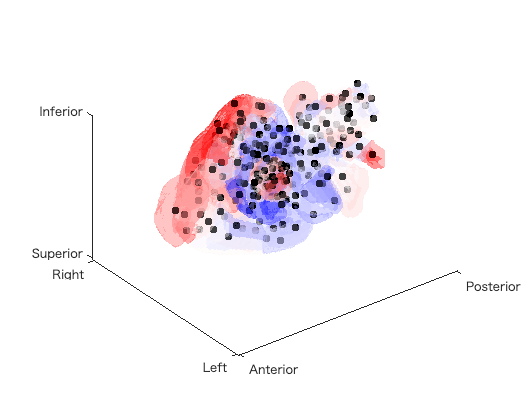

colorList = redblue_cp;
erodeSize = 2;
% u
figure
for ns = 1:NStructureOh
erodeim = imerode(ANO100_ConMatIndOh_subCompManually_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[3 2 1]);
colorListIndex = uValuePerRegionDim1_256split(ns) + 128;
if colorListIndex == 0
   colorListIndex = 1;
end
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(colorListIndex,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList_subCompManually(:,1);
XCs = gaussianCenterCoordList_subCompManually(:,2);
ZCs = gaussianCenterCoordList_subCompManually(:,3);
scatter3(XCs,ZCs,YCs,50,'k','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})

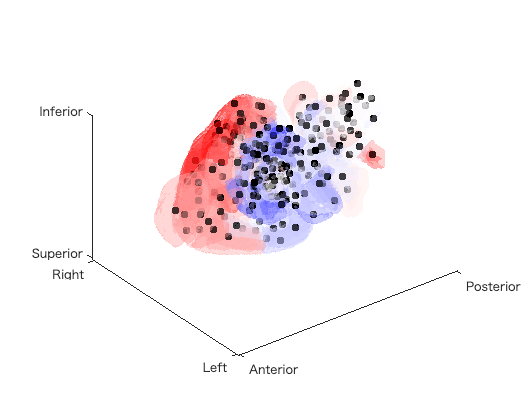


% v
figure
for ns = 1:NStructureOh
erodeim = imerode(ANO100_ConMatIndOh_subCompManually_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[3 2 1]);
colorListIndex = vValuePerRegionDim1_256split(ns) + 128;
if colorListIndex == 0
   colorListIndex = 1;
end
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(colorListIndex,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList_subCompManually(:,1);
XCs = gaussianCenterCoordList_subCompManually(:,2);
ZCs = gaussianCenterCoordList_subCompManually(:,3);
scatter3(XCs,ZCs,YCs,50,'k','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})

## Visualize Gene Expression (NMF50)

NMFCompNo = 1;

NMFValueMaxList = squeeze(max(NMFResults_Oh2014Sorted_50.W,[],1));
NMFValuePerRegionDimn_normalized = NMFResults_Oh2014Sorted_50.W(:,NMFCompNo) / NMFValueMaxList(NMFCompNo);
NMFValuePerRegionDimn_256split = round(NMFValuePerRegionDimn_normalized*256);

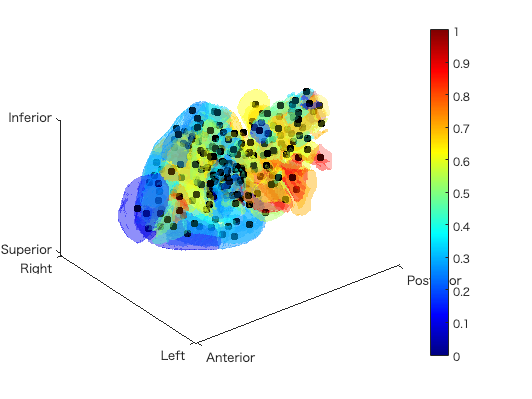

colorList = jet;
erodeSize = 2;

figure
colormap(jet);

for ns = 1:NStructureOh
erodeim = imerode(ANO100_ConMatIndOh_subCompManually_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[3 2 1]);
colorListIndex = NMFValuePerRegionDimn_256split(ns);
if colorListIndex == 0
   colorListIndex = 1;
end
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(colorListIndex,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList_subCompManually(:,1);
XCs = gaussianCenterCoordList_subCompManually(:,2);
ZCs = gaussianCenterCoordList_subCompManually(:,3);
scatter3(XCs,ZCs,YCs,50,'k','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})

colorbar

## Visualize Gene Expression (Each Gene Expression)

geneIndex = 25; % Epha1:2010 ,Ephb1:1341 ,Efnb2: 25

geneExpMaxList = squeeze(max(expEnergyMatrixOh_nonMissing_normalizzed_sorted,[],1));
geneExpPerRegionDimn_normalized = expEnergyMatrixOh_nonMissing_normalizzed_sorted(:,geneIndex) / geneExpMaxList(geneIndex);
geneExpPerRegionDimn_256split = round(geneExpPerRegionDimn_normalized*256);

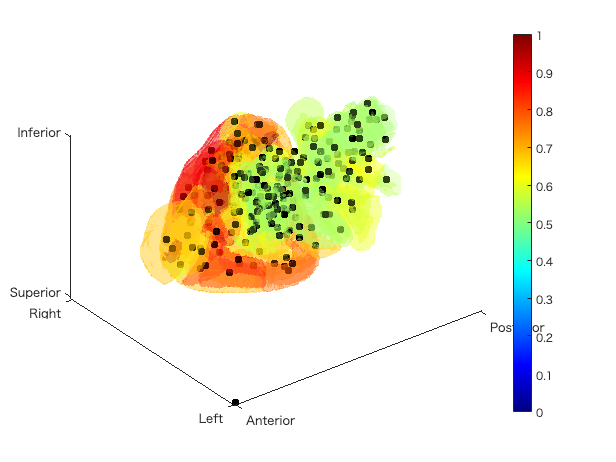

colorList = jet;
erodeSize = 2;

figure
colormap(jet);

for ns = 1:NStructureOh
erodeim = imerode(ANO100_ConMatIndOh_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[3 2 1]);
colorListIndex = geneExpPerRegionDimn_256split(ns);
if colorListIndex == 0
   colorListIndex = 1;
end
strctSurfNs = isosurface(1:AP100Size,1:LR100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(colorListIndex,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
YCs = gaussianCenterCoordList(:,1);
XCs = gaussianCenterCoordList(:,2);
ZCs = gaussianCenterCoordList(:,3);
scatter3(XCs,ZCs,YCs,50,'k','o','filled')
view(3)
axis equal
xlim([0,AP100Size])
ylim([0,LR100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,LR100Size-hiatus])
yticklabels({'Left','Right'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Superior','Inferior'})

colorbar

## Plot Connection

% calculate Center Coord & Arrow Vector
load('connectionIndexPairListOhP005_sorted.mat')
NConnection = length(connectionIndexPairListOhP005_sorted);
sourceCoordList = zeros(NConnection,3);
targetCoordList = zeros(NConnection,3);
arrowVecList = zeros(NConnection,3);
for nCon = 1:NConnection
    sourceRegionIndex = connectionIndexPairListOhP005_sorted(nCon,1);
    targetRegionIndex = connectionIndexPairListOhP005_sorted(nCon,2);
    sourceCoord = gaussianCenterCoordList_subCompManually(sourceRegionIndex,:);
    targetCoord = gaussianCenterCoordList_subCompManually(targetRegionIndex,:);
    arrowVec = targetCoord - sourceCoord;
    sourceCoordList(nCon,:) = sourceCoord;
    targetCoordList(nCon,:) = targetCoord;
    arrowVecList(nCon,:) = arrowVec;
end

connectionVisualizeCoordStruct = struct('sourceCoordList',sourceCoordList,'targetCoordList',targetCoordList,'arrowVecList',arrowVecList);
save('tentative_connectionVisualizeCoordStruct.mat','connectionVisualizeCoordStruct')

% erode on, right only, center point
%{
colorList = lines(NStructureOh);
erodeSize = 2;
figure

Xqui = sourceCoordList(:,2);
Yqui = sourceCoordList(:,1);
Zqui = sourceCoordList(:,3);
Uqui = arrowVecList(:,2);
Vqui = arrowVecList(:,1);
Wqui = arrowVecList(:,3);
quiver3(Xqui,Yqui,Zqui,Uqui,Vqui,Wqui,'off','y','LineWidth',0.1)
hold on

YCs = gaussianCenterCoordList_subCompManually(:,1);
XCs = gaussianCenterCoordList_subCompManually(:,2);
ZCs = gaussianCenterCoordList_subCompManually(:,3);
scatter3(XCs,YCs,ZCs,50,'k','o','filled')
%
hold on
for ns = 1:NStructureOh
strctSurfNs = isosurface(1:AP100Size,1:DV100Size,1:LR100Size,imerode(ANO100_ConMatIndOh_subCompManually_onlyRight == ns,ones(erodeSize,erodeSize,erodeSize)),0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList(ns,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
%

view(3)
axis equal
xlim([0,AP100Size])
ylim([0,DV100Size])
zlim([0,LR100Size])
hiatus = 1;
xticks([0+hiatus,AP100Size-hiatus])
xticklabels({'Anterior','Posterior'})
yticks([0+hiatus,DV100Size-hiatus])
yticklabels({'Superior','Inferior'})
zticks([0+hiatus,LR100Size-hiatus])
zticklabels({'Left','Right'})
%}

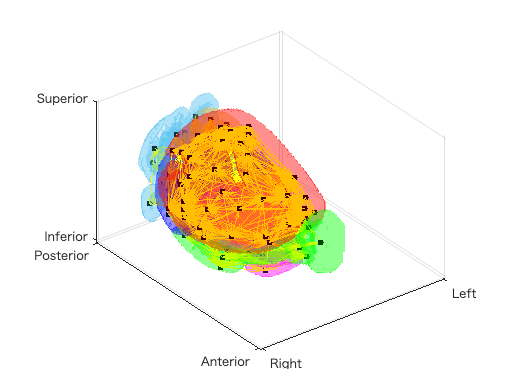

% erode on, right only, center point
colorList = lines(NStructureOh);
erodeSize = 2;
figure

DVqui = sourceCoordList(:,1);
DVqui = -(DVqui - DV100Size/2 - 0.5) + DV100Size/2 + 0.5;
APqui = sourceCoordList(:,2);
LRqui = sourceCoordList(:,3);
LRqui = -(LRqui - LR100Size/2 - 0.5) + LR100Size/2 + 0.5;
ArrowDVqui = arrowVecList(:,1);
ArrowDVqui = - ArrowDVqui;
ArrowAPqui = arrowVecList(:,2);
ArrowLRqui = arrowVecList(:,3);
ArrowLRqui = - ArrowLRqui;
quiver3(LRqui,APqui,DVqui,ArrowLRqui,ArrowAPqui,ArrowDVqui,'off','y','LineWidth',0.1)
hold on

CDVs = gaussianCenterCoordList_subCompManually(:,1);
CDVs = -(CDVs - DV100Size/2 - 0.5) + DV100Size/2 + 0.5;
CAPs = gaussianCenterCoordList_subCompManually(:,2);
CLRs = gaussianCenterCoordList_subCompManually(:,3);
CLRs = -(CLRs - LR100Size/2 - 0.5) + LR100Size/2 + 0.5;
sz = 30;
scatter3(CLRs,CAPs,CDVs,sz,'k','o','filled')
%
hold on
for nmr = 1:NMajorRegion
erodeim = imerode(ANO100_majorRegion_onlyRight == nmr,ones(erodeSize,erodeSize,erodeSize));
erodeim = permute(erodeim,[2 3 1]);
erodeim = flip(erodeim,2);
erodeim = flip(erodeim,3);
strctSurfNs = isosurface(1:LR100Size,1:AP100Size,1:DV100Size,erodeim,0);
strctPatchNs = patch(strctSurfNs,'FaceColor',colorList13(nmr,:),'FaceAlpha',.25,'EdgeColor','none');
hold on
end
%}

view(3)
axis equal
xlim([0,LR100Size])
ylim([0,AP100Size])
zlim([0,DV100Size])
hiatus = 1;
xticks([0+hiatus,LR100Size-hiatus])
xticklabels({'Right','Left'})
yticks([0+hiatus,AP100Size-hiatus])
yticklabels({'Anterior','Posterior'})
zticks([0+hiatus,DV100Size-hiatus])
zticklabels({'Inferior','Superior'})